This demo shows how we can setup CST optimizer such that the cost function is evaluated in Matlab. This functionality may be useful for example for:

- evaluating a complex cost function without using CST's VBA capabilities;

- saving some data after each optimization step;

- performing co-optimization in conjunction with other software tools, e.g. Keysight ADS;

- calculating custom results which are not available in CST Navigation Tree.

clc
clear

Open the project for optimization

CSTProject = 'CST\Single_dipole_MLOpt.cst';
CST = TCSTInterface();
CST.OpenProject(CSTProject);

Connected to project "E:\01_Toolboxes\CSTMWS-Matlab-Interface\Demos\CST\Single_dipole_MLOpt.cst"


# Setup CST optimization in which the cost function is calculated in Matlab

After opening the project, we need to assign the Matlab function `CalcCostFn` as the cost function for the optimization.

The cost function must be a separate m-file in Matlab search path, and it must have one input argument and one output argument:

When this function is called from CST, `CSTProject` will contain the CST project name (without .cst extension) including full path to it. This can be used to connect to the project using `TCSTInterface` and get results of the solution at current optimization iteration in order to calculate the cost function value.

The function must return a real scalar finite numeric value `Res`, which will be returned to CST optimizer.

The content of the cost function for this example is

demohlpPrintFileContent('CalcCostFn.m', inf);

--------- Content of "CalcCostFn.m" -----------
function Res = CalcCostFn(CSTProject)
% CST calls this function passing the full project file name without
% extension as the argument.


% --------------- Main job: calculate the cost function -------------------
% Create the CST interface object and connect to the CST project
CST = TCSTInterface([CSTProject '.cst']);
% Get S-params (S11 for the example project, since we have only 1 port) for
% the current run (RunID=0) and Freq=1 GHz
S = CST.GetSParams(0,[],[],[],1); 
% The cost function here is simply |S11| in [dB]
Res = 20*log10(abs(S));
% -------------------------------------------------------------------------


% -------- Additional action: plot initial, best and current S11 ----------
% Get S-params (S11 for the example project, since we have only 1 port) for
% the current run (RunID=0)
[S11, Freq] = CST.GetSParams(0);  
S11db = 20*log10( abs( squeeze(S11) ) );
% Helping function to plot S11
PlotOptimizationProgress(Res, S11db, Fr

In this function we not only calculate the value of the cost function, but additionally plot S11 versus frequecny at each optimization iteration, something like this:

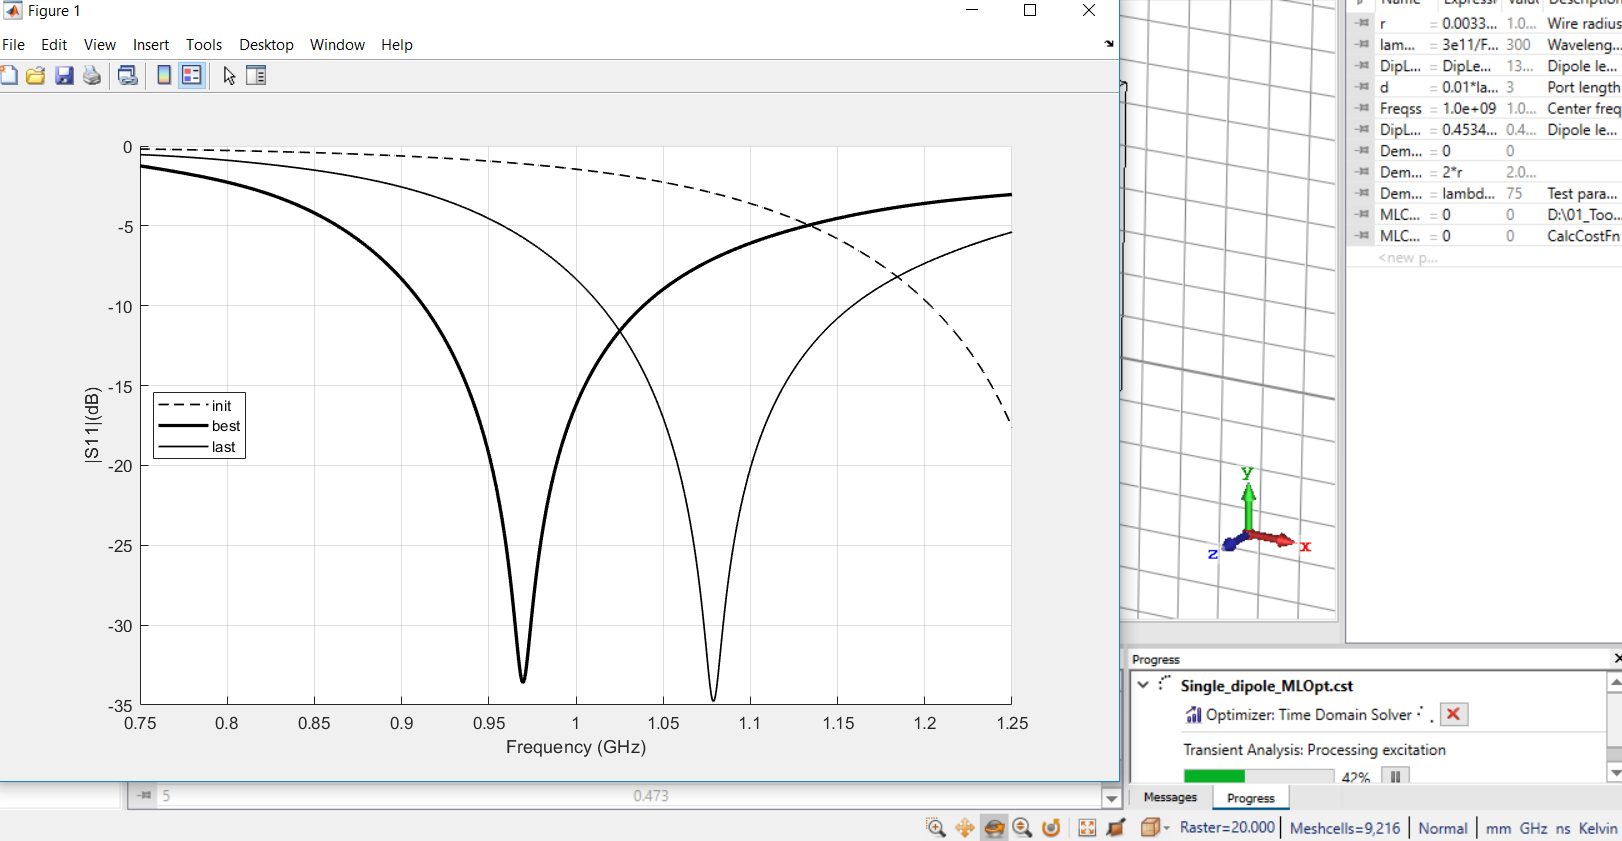

So, now we prepare the CST project to run our cost function "`CalcCostFn.m`" after each solution:

CostFunctionName = 'CalcCostFn'; % without .m extension
CST.SetMatlabCostFunction(CostFunctionName);


-----------------------------------------------------------------------------------------------------------------
To finalize optimization setup in CST do the following steps:
  1. Add Template Based Post-Processing step:
    a) Go to Template Based Post-Processing (Shift+P) 
    b) Under category "Misc" select "Run VBA Code"
    c) Place the following code there and press Ok:
Sub Main
  RunScript(GetProjectPath("Project")+GetPathSeparator()+"CalcCostFnInMatlab.mcr")
End Sub
    d) (optionally) Select added post-processing step and press "Evaluate" to check that Matlab script is called and works as expected
  2. Add optimization goal:
    a) Go to Simulation tab - Optimizer - Goals - Add New Goal
    b) Under "Result Name" select newly added post-Processing step (like "TBPP 0D: Run VBA Code")
    c) Complete setting the goal and press Ok
Now the project is ready to evaluate the cost function in Matlab.
---------------

As described in the ouput of this function, some settings must be done in CST manually:

1. Add Template Based Post-Processing step, which runs created by the interface macro:

        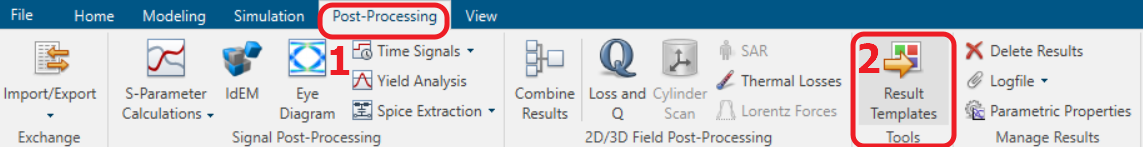

        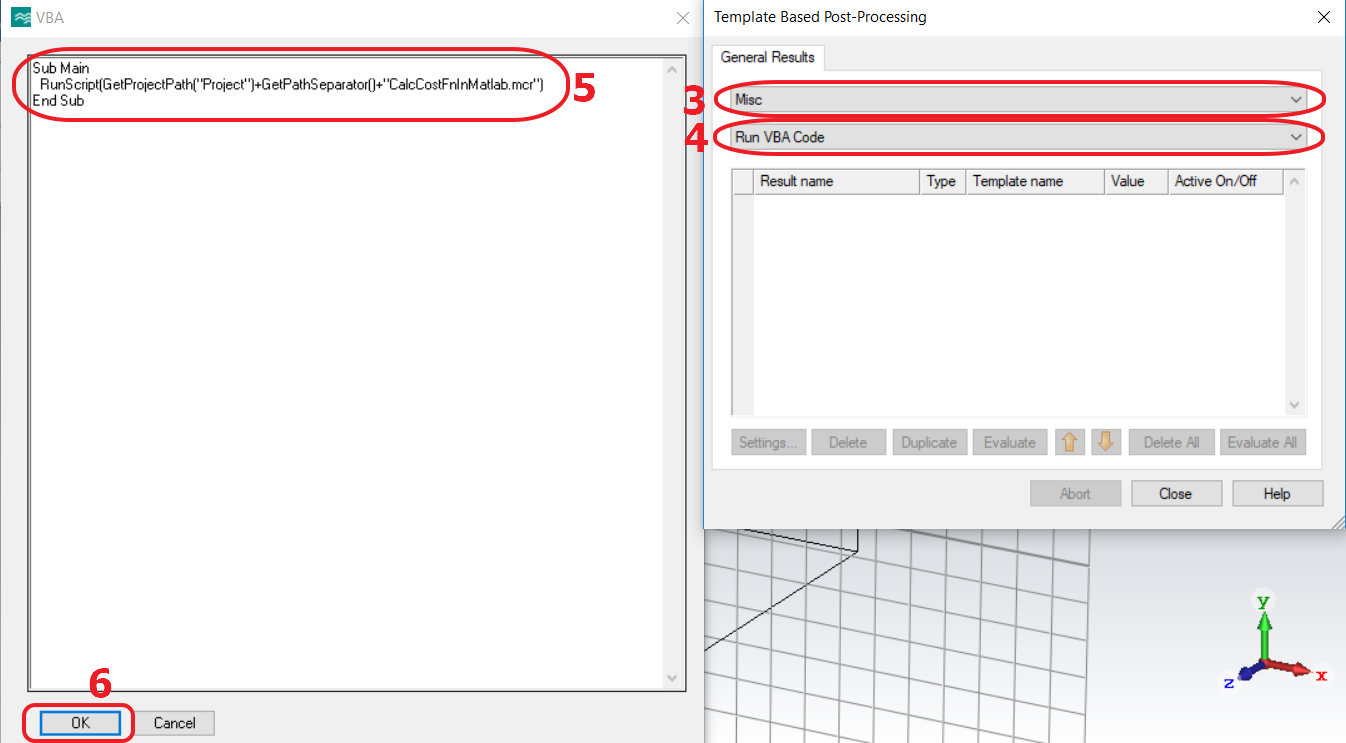

        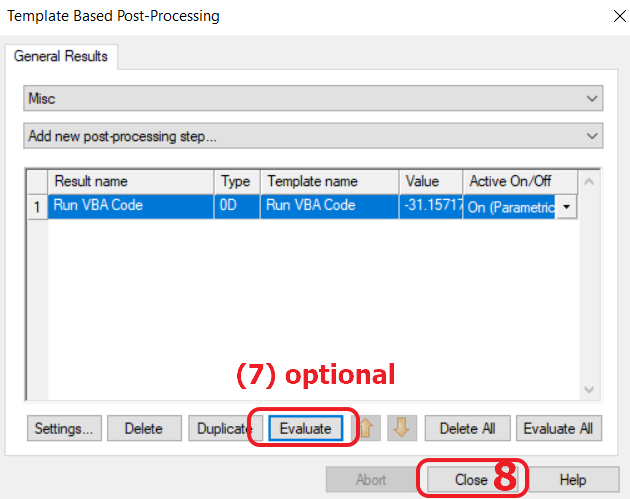    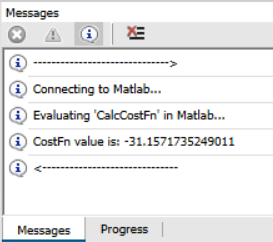

2. Add optimization goal using the created above post-processing step as the "Result Name":

        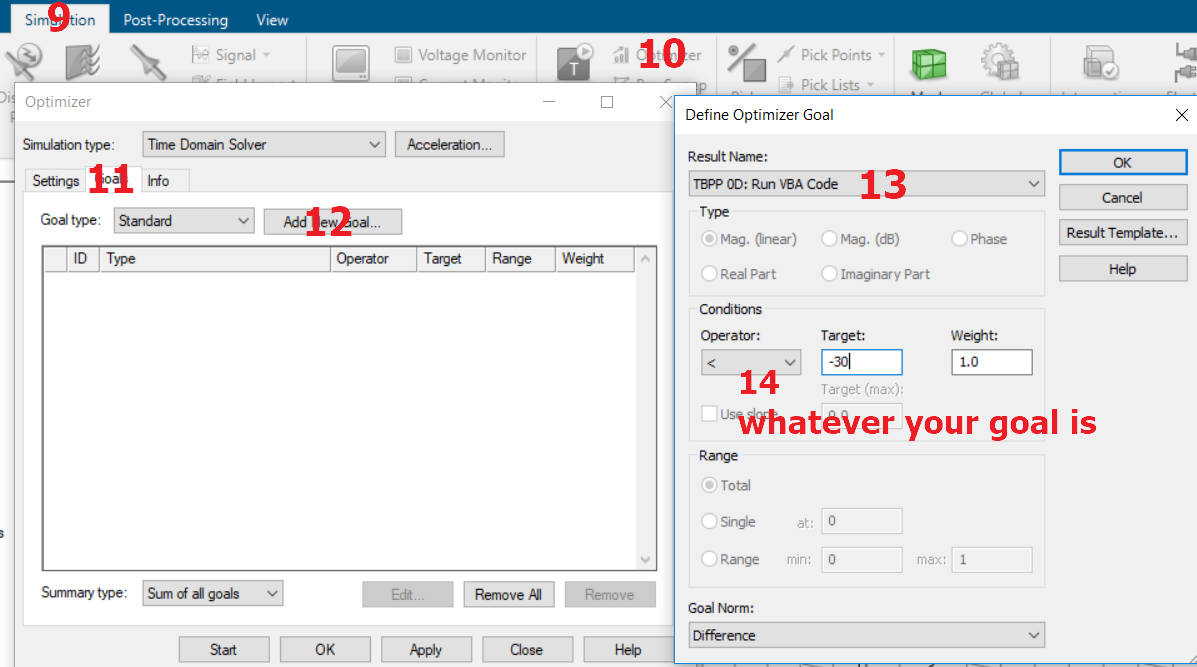

Now the CST optimizer will use the value returned by the Matlab function `CalcCostFn` as the optimization cost function. So, just start the optimization in CST as usual.

**Below there are some notes regarding this functionality.**

- You need to call `SetMatlabCostFunction` only once for each CST project. This will enable Matlab ActiveX server, and will save a macro file to the project directory, which will do actuall calling of Matlab.

- By default the ActiveX server is not enabled in Matlab, so if the Matlab session was re-opened for some reason, the ActiveX server should be enabled again by calling `SetMatlabCostFunction` method again, or executing `enableservice('AutomationServer',true)` in the Matlab command window.  

- The optional step 7 can help to debug the cost function. All required by it results must be present in the CST project (you can just simply simulate it once before).

- Do not print to *stderr* inside the cost function m-file (e.g. by using `fprintf(2,'Message')`), otherwise CST macro will "think" there was en error.

- If the cost function is called from CST and paused at a break point, do not press Stop in Matlab, otherwise in some cases (at least at my computer) CST can hang. Just press Continue, even if there is an error. 

- If any error occures in the cost function, it will be reported in the CST window "*Messages*", instead of Matlab command window.

- It is not necessary to use the created post-processing step in an optimization. It can be used to calculate a custom result after each simulation or optimization iteration. It will be stored in the tree folder "*Tables*" in the CST *Navigation Tree*. For example, in one of the projects I used it to calculate the far-field polarization rotation angle using the following "cost function" (which in fact is not a cost function anymore, but just a post-processing function):